clc
clear all
close all

%loading data
load('Received.mat')

25 m depth reciever


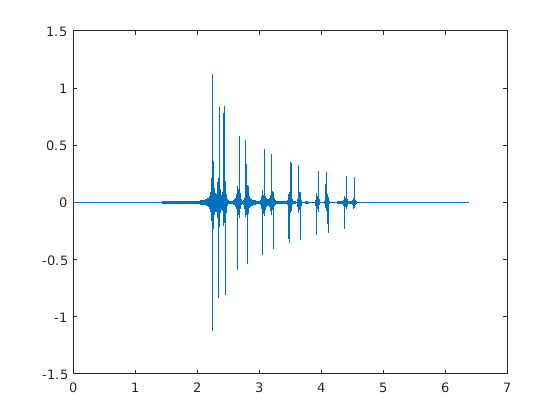

50 m depth reciever


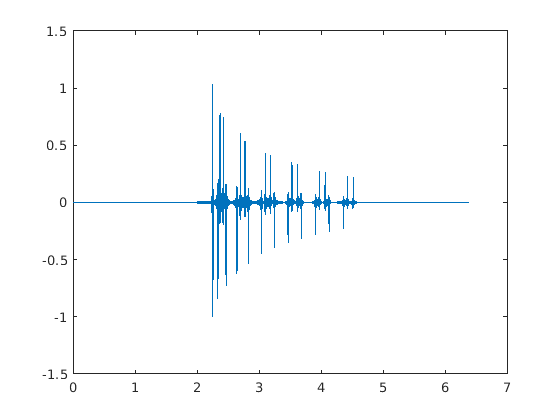

75 m depth reciever


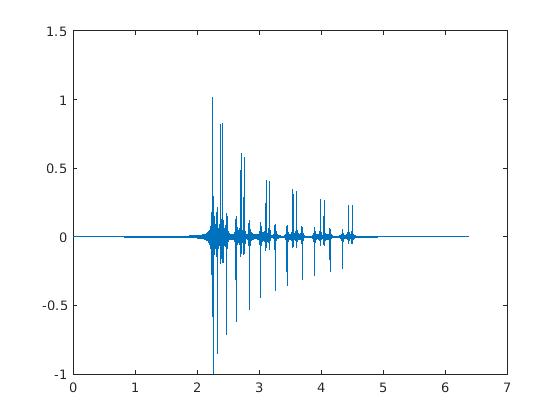

100 m depth reciever


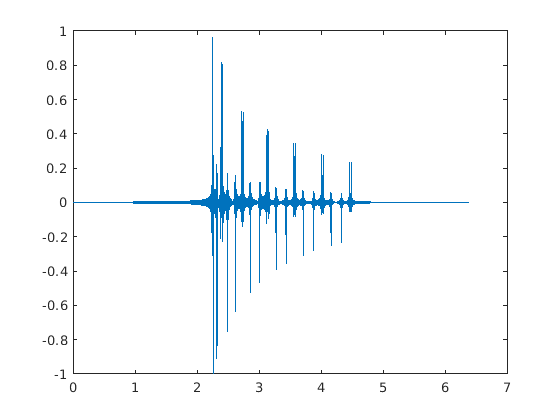

125 m depth reciever


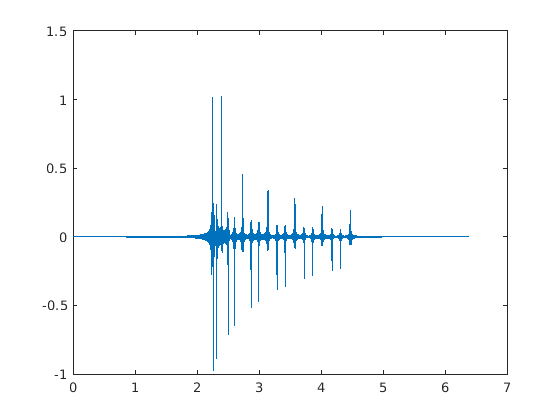

150 m depth reciever


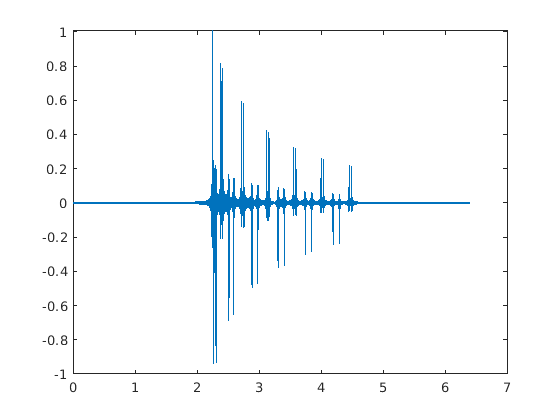

175 m depth reciever


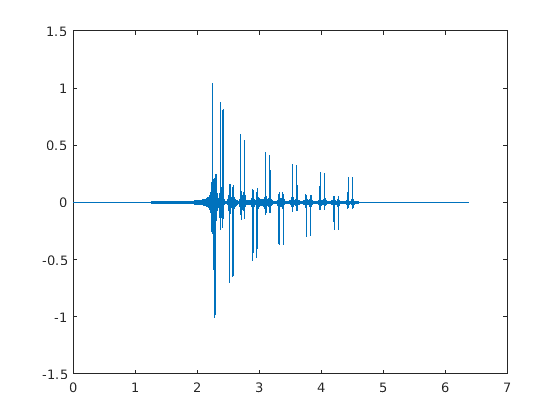

200 m depth reciever


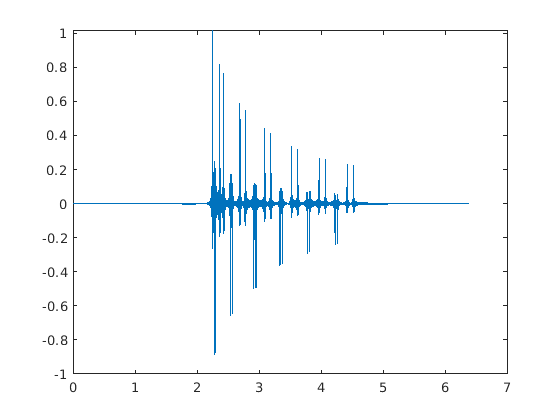

225 m depth reciever


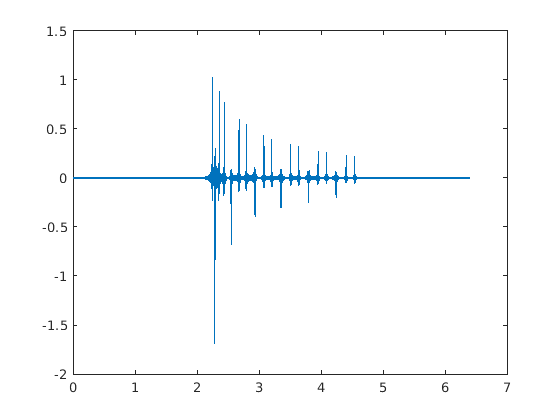


dt = 2e-4;
t = dt:dt:6.4;
for i =1:9
    disp(sprintf('%d m depth reciever', i*25))
    figure()
    plot(t,RecSig(i,:))
    hold off
end

## **The first peak is at 2.2492 secs away. so roughly the source is 2.2492 * 1500 = 3373.**

## **8  m away.**

dt = 2e-4;
fs = 1/dt;
t= dt:dt:6.4;


%coordinate to search for the focusing
all_x_coor = -3500:70:-2000;
all_y_coor = 15:50:350;
t = -6.4+dt:dt:6.4;
t = dt:dt:6.4;
energy_values = zeros(size(all_y_coor, 2), size(all_x_coor, 2));
ii = 0;
for i = all_x_coor
    ii = ii+1;
    jj= 0;
    i
    for j=all_y_coor
        jj = jj+1;
        
        all_zs =  [1:9]*25; %recievers pos z
        %all_R = [];
        all_x = zeros(size(t,2),1);
        
        for z=all_zs 
            R = RecSig(z/25,:)';
            
            
            new_R = zeros(size(t,2)-size(R,1),1);
            C1 = cat(1,new_R,R); %new padded signal
            C1 = flip(C1);
            new_x = green(0,z,i,j,C1,t);
            all_x = all_x + new_x;
            %figure()
            %plot(all_x)
            %all_R = horzcat(all_R,R);
        end
        energy_x = all_x.^2;
        energy_values(jj, ii) = sum(sum(energy_x));
        
        sum(sum(energy_x));
        jj
        
    end
    ii
    
end

i = -3500

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 1

i = -3430

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 2

i = -3360

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 3

i = -3290

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 4

i = -3220

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 5

i = -3150

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 6

i = -3080

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 7

i = -3010

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 8

i = -2940

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 9

i = -2870

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 10

i = -2800

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 11

i = -2730

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 12

i = -2660

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 13

i = -2590

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 14

i = -2520

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 15

i = -2450

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 16

i = -2380

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 17

i = -2310

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 18

i = -2240

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 19

i = -2170

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 20

i = -2100

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 21

i = -2030

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

ii = 22

% energy_values = energy_values;
% hold off
% image(all_x_coor, all_y_coor,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
% colorbar

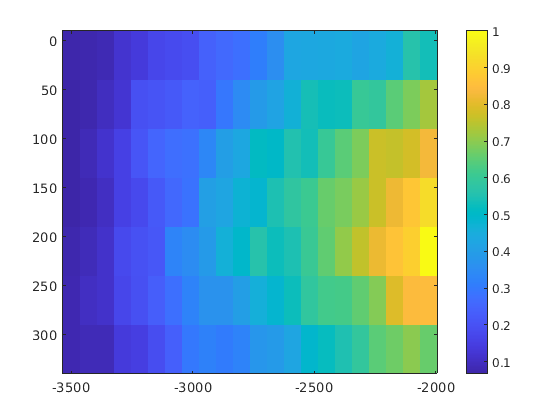

%energy_values = energy_values';
image(all_x_coor, all_y_coor,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
colorbar

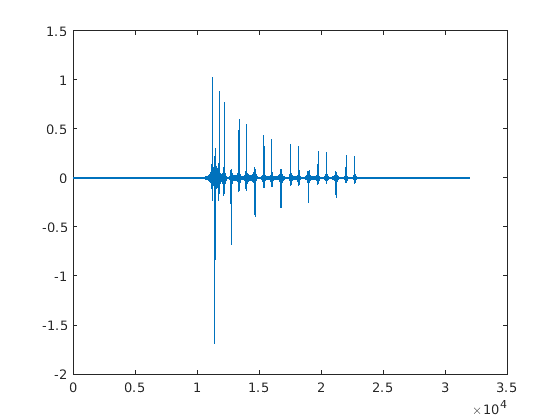

%beta = 50;
%signal = sinc(beta.*t)';
%plot(t,signal)
%rcv = green(0,100, 3300, 100, signal, t );
t = -6.4+dt:dt:6.4;
figure
plot(R)

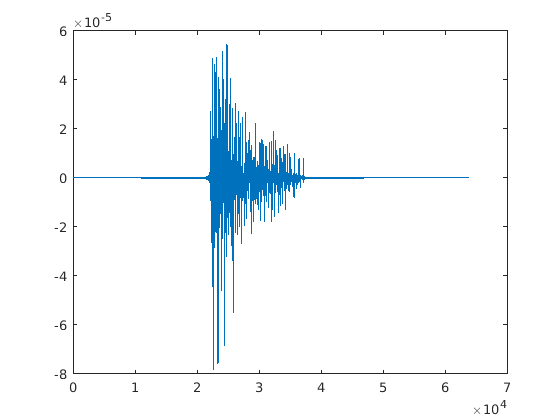

new_R = zeros(size(t,2)-size(R,1),1);
C1 = cat(1,R,new_R);
figure
%flipted_rcv = flip(rcv);
sig = green(0, 100, -3300, 100, C1,t);
figure
plot(sig)

t = -6.4+dt:dt:6.4;

for i = 1:9
    recv_signal = RecSig(i,:);
    new_R = zeros(size(t,2)-size(recv_signal,2),1);
    C1 = cat(1,new_R,recv_signal);
    figure()
    plot(C1)
    reversed_recv_signal = flip(C1);
    figure()    
    plot(t,reversed_recv_signal)
    
    sig = green(3373, i*25, 0, 100, reversed_recv_signal,t);
    
    figure()
    plot(sig)
    
end

Error using cat
Dimensions of arrays being concatenated are not consistent.

function R = green(xs, zs, x, z,signal, t)
h = 350; %max_height
xs = xs;
zs = zs;
x = x;
z = z;
c = 1500;

dt = 2e-4;
fs = 1/dt;

%fs = 1.0e4;

r0 = sqrt((x-xs)^2 + (z-zs)^2);
this_signal = delayseq(signal,r0/c,fs);
R = this_signal/(4*pi*r0);

for j = -8:8
    if j ==0
        continue
    end
    if rem(j,2)==0
       r = sqrt((x-xs)^2 + (z-zs+j*h)^2);
       eps = 1;
    else
       r = sqrt((x-xs)^2 + (z+zs-(j+1)*h)^2);
       eps = -1;
    end
    this_signal = delayseq(signal,r/c,fs);
    R = R+(eps/(4*pi*r) *this_signal);
end

end


